%LINK: https://youtu.be/P7T5PEoCVXg

%image 2
im1 = imread('https://i.postimg.cc/hPx5PBMC/FB787E3C-23AC-4F66-918A-14A95DB9C010.jpg');
im2 = imread('https://i.postimg.cc/CMR2XD8p/721-DDDE7-7-B9-C-4-D0-D-8-D9-C-CAF9231605-DC.jpg');
im3 = imread('https://i.postimg.cc/ZYXQSRPB/334656-C7-BCD7-41-DB-B954-0-FFD3611-C200.jpg');
im4 = imread('https://i.postimg.cc/sxG5m31b/A93-CBBD0-4-CE1-412-D-911-A-04-AF6-F20-D2-E7.jpg');
im5 = imread('https://i.postimg.cc/g2Vq1c4W/4-D3709-A5-A854-4-B9-D-9-D10-9934-A7-E9-AE6-D.jpg');


ims = {im1 im2 im3 im4 im5};
warp1 = [1.2585 0.0344 -151.8013; 0.1218 1.0621 -23.9287; .0005 -.0001 1];
warp2 = [.7506 -0.0256 300.0689; -.0622 .9400 25.0053; -.0004 0 1];
warp3 = [1.5616 0.1013 -218.6167; 0.0212 1.1514 43.9278; .0007 -.0001 1]

warp3 =     1.5616    0.1013 -218.6167
    0.0212    1.1514   43.9278
    0.0007   -0.0001    1.0000


warp4 = [.3915 .0328 626.7355; -.1476 1.003 20.7856; -.0007 .0001 1]

warp4 =     0.3915    0.0328  626.7355
   -0.1476    1.0030   20.7856
   -0.0007    0.0001    1.0000



mid = ceil(length(ims)/2);
current = ims{mid};
idx = 0;
for j = 1:length(ims) - 1
    k = j;
    if mod(k, 2) == 1
        k = -k;
    end
    idx = idx + k;
    next = ims{mid+idx};

    % Took warping values from previous runs using getCoords.
    % Can comment out to manually define points and recalculate warping.
    if j==1
        warp = warp1;
    elseif j == 2
        warp = warp2;
    elseif j == 3
        warp = warp3;
    elseif j == 4
        warp = warp4;
    else
    
        [ccs_x, ccs_y]= getCoords(current)
        [ncs_x, ncs_y] = getCoords(next)
    
        A = [];
        B = [];
        for i = 1:size(ccs_x, 2)
            x = ncs_x(i);
            y = ncs_y(i);
            xh = ccs_x(i);
            yh = ccs_y(i);
            a = [x, y, 1, 0, 0, 0, -x*xh, -y*xh; 0, 0, 0, x, y, 1, -x*yh, -y*yh];
            A = [A;a];
            b = [xh;yh];
            B = [B;b];
        end
        H = A\B;
        
        warp = [H(1), H(2), H(3); H(4), H(5), H(6); H(7), H(8), 1]

    end

    
    tform = projective2d(warp');
    output = imwarp(next, tform);
    %imshow(output)

    current = stitch(output, current);

end

oldzs = oldzs(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

mask = mask(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

mask_s = mask_s(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

oldzs = oldzs(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

mask = mask(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

mask_s = mask_s(:,:,1) =

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

oldzs = oldzs(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

mask = mask(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

mask_s = mask_s(:,:,1) =

  Columns 1 through 999

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

oldzs = oldzs(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

mask = mask(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

mask_s = mask_s(:,:,1) =

  Columns 1 through 999

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

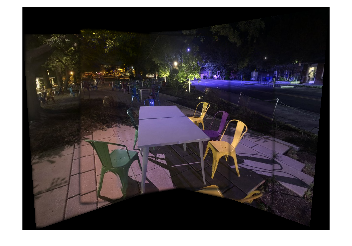


imshow(current)

function res = stitch(output, current)
    [output_y, output_x, ~] = size(output);
   
    opmy_start = floor(.35*output_y);
    opmy_end = output_y-opmy_start;
    opmx_start = floor(.35*output_x);
    opmx_end = output_x-opmx_start;
    output_pattern_match = output(opmy_start:opmy_end, opmx_start:opmx_end, :);
    c = normxcorr2(im2gray(output_pattern_match),im2gray(current));
    [ypeak,xpeak] = find(c==max(c(:)));
    
    %top-left coords of where opm is
    yoffset = ypeak-size(output_pattern_match,1);
    xoffset = xpeak-size(output_pattern_match,2);
    
    true_yoffset = yoffset-opmy_start;
    true_xoffset = xoffset-opmx_start;

    y_shift = 0;
    x_shift = 0;

    newzs = uint8(zeros(size(current)));
    if true_yoffset < 0
        newzs = padarray(newzs, [-1*true_yoffset 0], 0, 'pre');
        y_shift = y_shift - true_yoffset;
    end
    if true_xoffset < 0
        newzs = padarray(newzs, [0 -1*true_xoffset], 0, 'pre');
        x_shift = x_shift - true_xoffset;
    end


    %NEW = the output of the warp
    newzs(1 + true_yoffset + y_shift:output_y + true_yoffset + y_shift, 1 + true_xoffset + x_shift:output_x + true_xoffset + x_shift, :) = output;
    
    % cut/paste
    %empty = uint8(current == 0);
    %current = current + empty .* newzs(1 + y_shift:size(current, 1) + y_shift, 1 + x_shift:size(current,2) + x_shift, :)
    %newzs(1 + y_shift:size(current, 1) + y_shift, 1 + x_shift:size(current,2) + x_shift, :) = current;
    %res = newzs

    % pyramid blending / feather blending
    oldzs = im2double(zeros(size(newzs)))
    %OLD = existing base image(s)
    oldzs(1 + y_shift:size(current, 1) + y_shift, 1 + x_shift:size(current,2) + x_shift, :) = im2double(current);
    
    mask = zeros(size(oldzs));
    mask(1 + y_shift+12:size(current, 1) + y_shift-12, 1 + x_shift+12:size(current,2) + x_shift-12, :) = 1;

    mask = mask.*(1-(oldzs <= .03))  % FOR SOME REASON THIS MESSES UP WARPing

    res = feather_blend(im2double(newzs), oldzs, mask, 5);

end



function [poly_x, poly_y] = getCoords(im)
    % Asks user to draw polygon around input image.  
    fig=figure; hold off; imagesc(im); axis image;
    poly_x = [];
    poly_y = [];
    while 1
        figure(fig)
        [x, y, b] = ginput(1);
        if b=='q'
            break;
        end
        poly_x(end+1) = x;
        poly_y(end+1) = y;
        hold on; plot(poly_x, poly_y, '*-');
    end
    close(fig);

    %p' = Hp
    %p' = ims(current)
    %p = ims(next)
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% These are your functions that implement the blending method
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function im_feather = feather_blend(im_bg, im_s, mask_s, blur)
    
    %COMPLETE YOUR CODE HERE...
    %First blur the mask
    %Then alpha composite
    
    
    mask_s = imfilter(mask_s, fspecial('gaussian',6*blur, blur))

    im_feather = im_bg-im_bg.*mask_s;
    im_feather = im_feather+im_s.*mask_s;

end

